% Convex Optimization
% Hw5
% Q2-Gray Scale Image interpolation

clear;
clc;
close all;

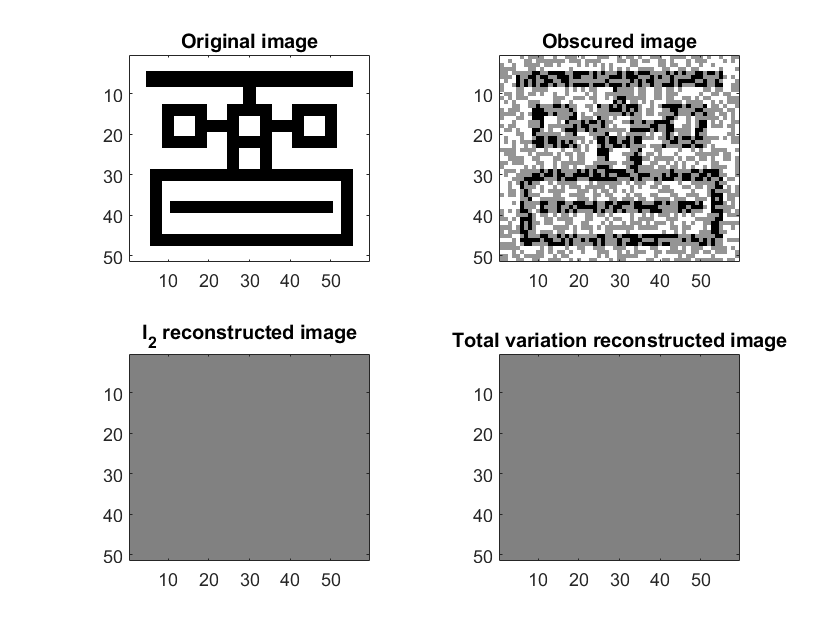

run('tv_img.m')

Ux = 0;Uy=0;
cvx_begin
variable Ul2(m, n);
Ul2(Known) == Uorig(Known); % Fix known pixel values.[interpolation constraints]
Ux = Ul2(1:end,2:end) - Ul2(1:end,1:end-1); % x (horiziontal) differences
Uy = Ul2(2:end,1:end) - Ul2(1:end-1,1:end); % y (vertical) differences
minimize(norm([Ux(:); Uy(:)], 2)); % l2 roughness measure [norm 1 --> total variation]
cvx_end

 
Calling SDPT3 4.0: 5909 variables, 1500 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 1500
 dim. of socp   var  = 5909,   num. of socp blk  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.8e+01|1.4e+00|5.7e+05| 0.000000e+00  0.000000e+00| 0:0:00| spchol  1  1 
 1|0.947|1.000|2.0e+00|1.3e-05|4.8e+04|-7.203869e+03 -1.105913e+04| 0:0:00| spchol  1  1 
 2|1.000|1.000|8.0e-08|1.3e-06|4.6e+03|-3.790494e+03 -8.409286e+03| 0:0:00| spchol  1  1 
 3|1.000|0.960|6.8e-09|2.0e-07|1.3e+02|-5.260618e

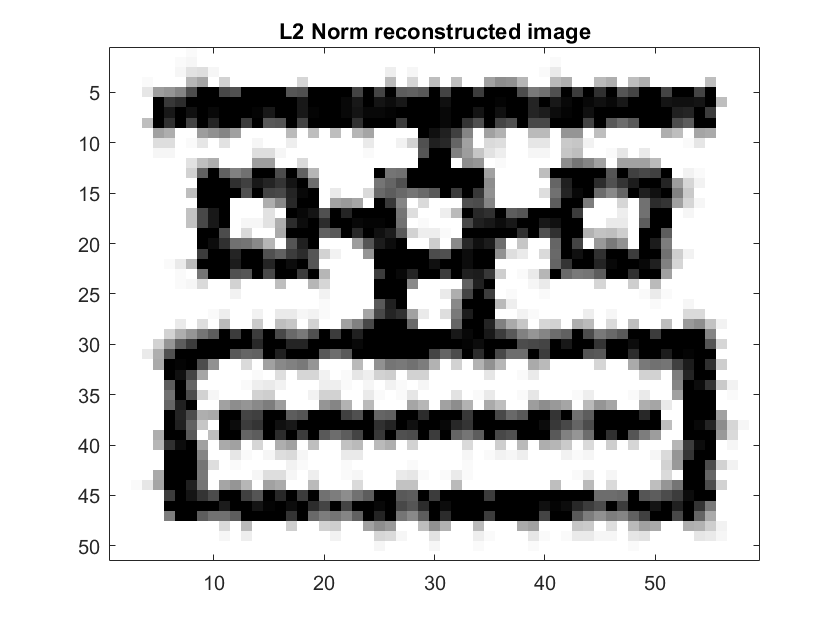

figure()
colormap gray;
imagesc(Ul2)
title('L2 Norm reconstructed image');

Ux = 0;Uy=0;
cvx_begin
variable Utv(m, n);
Utv(Known) == Uorig(Known); % Fix known pixel values. [interpolation constraints]
Ux = Utv(1:end,2:end) - Utv(1:end,1:end-1); % x (horiziontal) differences
Uy = Utv(2:end,1:end) - Utv(1:end-1,1:end); % y (vertical) differences
minimize(norm([Ux(:); Uy(:)], 1)); % tv roughness measure [norm 1 --> total variation]
cvx_end

 
Calling SDPT3 4.0: 11832 variables, 4425 equality constraints
------------------------------------------------------------

 num. of constraints = 4425
 dim. of linear var  = 11816
 dim. of free   var  = 16
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|2.9e+01|6.9e+03|1.8e+10| 5.812604e+07| 0:0:00|1.8e+10|1.0e+00|1.0e+00| spchol 1   1
 1|0.000|0.000|2.9e+01|6.9e+03|1.8e+10| 5.813053e+07| 0:0:00|1.8e+10|1.0e+00|1.0e+00| spchol 1   1
 2|0.000|0.000|2.9e+01|6.9e+03|1.8e+10| 5.813623e+07| 0:0:00|1.8e+10|1.0e+00|1.0e

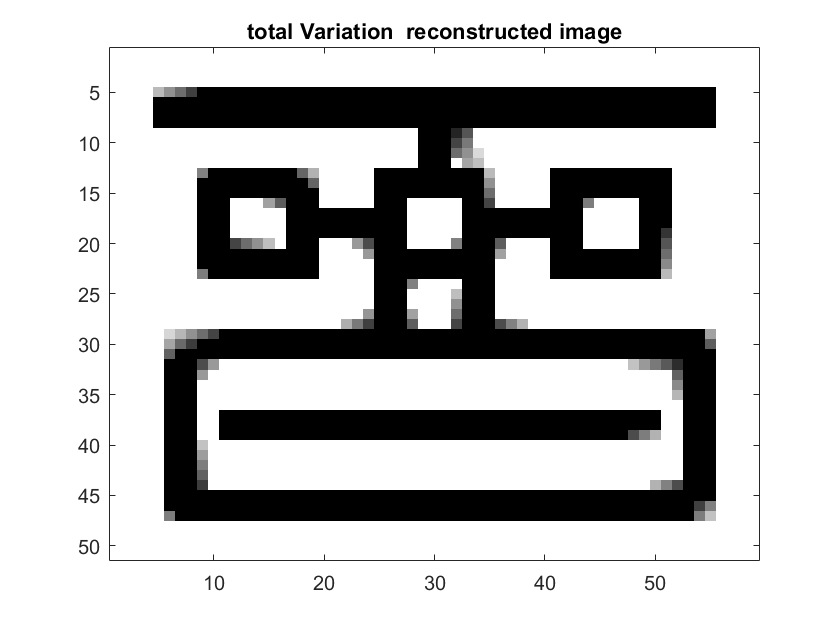

figure()
colormap gray;
imagesc(Utv)
title('total Variation  reconstructed image');

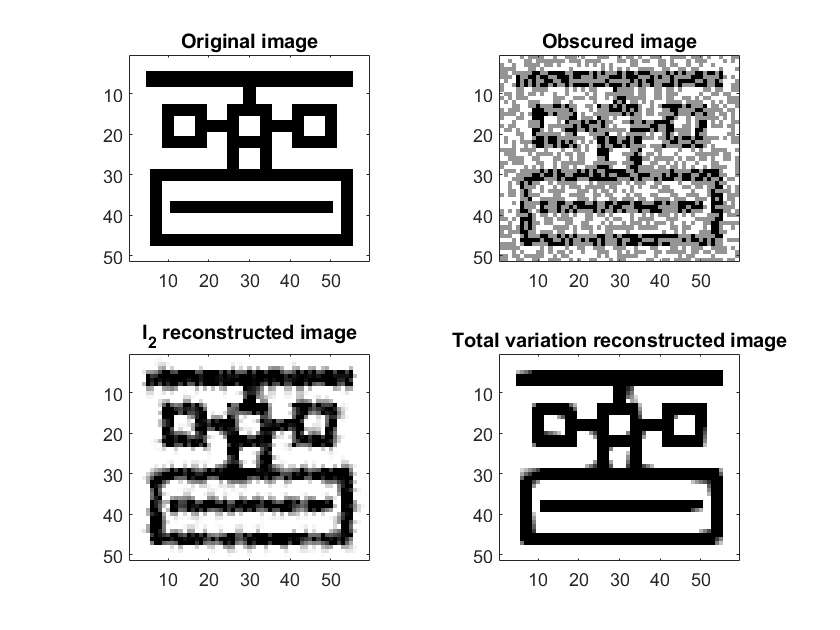

% Time for comparison:
% Graph everything.
figure(); cla;
colormap gray;

subplot(221);
imagesc(Uorig)
title('Original image');
axis image;

subplot(222);
imagesc(Known.*Uorig + 256-150*Known); % Noisy img
title('Obscured image');
axis image;

subplot(223);
imagesc(Ul2);
title('l_2 reconstructed image');
axis image;

subplot(224);
imagesc(Utv);
title('Total variation reconstructed image');
axis image;